# Color from Image Segmentation

Goal: choose colors from segmented regions 

https://www.mathworks.com/help/images/marker-controlled-watershed-segmentation.html?prodcode=IP&language=en

Method: Segment regions by Opening-Closing by Reconstruction

clear all;
close all;

## 0) Import the data

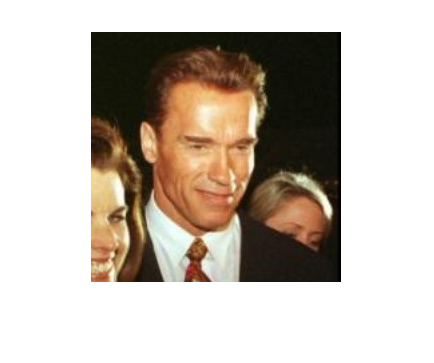

% import the data
%im = im2double(imread('../lfw/Abdel_Nasser_Assidi_0002.jpg'));
%im = im2double(imread('../lfw/Avril_Lavigne_0001.jpg'));
%im = im2double(imread('../lfw/Ai_Sugiyama_0002.jpg'));
%im = im2double(imread('../lfw/Ainsworth_Dyer_0001.jpg'));
%im = im2double(imread('../lfw/Alejandro_Toledo_0003.jpg'));
%im = im2double(imread('../lfw/Allyson_Felix_0003.jpg'));
im = im2double(imread('../lfw/Arnold_Schwarzenegger_0004.jpg'));
imshow(im)

## Color Reduction by Segmentation

Steps:

- Opening-Closing by Reconstruction: smooth inside of regions while preserving strong boundaries between regions

- Use gradient magnitude to extract region boundaries

- Region Labeling to identify regions

- Color each region with its mean color value

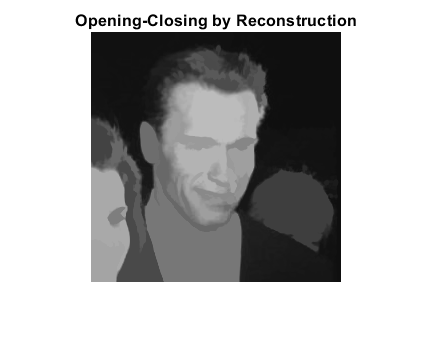

% hyperparameters
gd_thresh = 0.1; % threshold for region boundaries detection
min_edge = 50; % smallest size of edge allowed
se_size = 20; % size of structural element
gamma = 0.9; % color adjustement

% grayscale image
im_g = rgb2gray(im);

% smooth the image into very distinct regions
se = strel('disk', se_size); % structural element
    % opening by reconstruction
im_e = imerode(im_g, se);
im_obr = imreconstruct(im_e, im_g);
    % closing by reconstruction
im_obr_d = imdilate(im_obr, se);
im_ocbr = imreconstruct(imcomplement(im_obr_d), imcomplement(im_obr));
im_ocbr = imcomplement(im_ocbr);

imshow(im_ocbr)
title('Opening-Closing by Reconstruction')

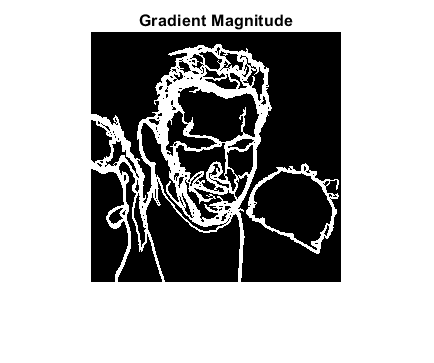


% extract the boundaries of the regions
gmag = imgradient(im_ocbr) > gd_thresh;
% filtrate small edges
gmag = bwareaopen(gmag, min_edge);

imshow(gmag)
title('Gradient Magnitude')

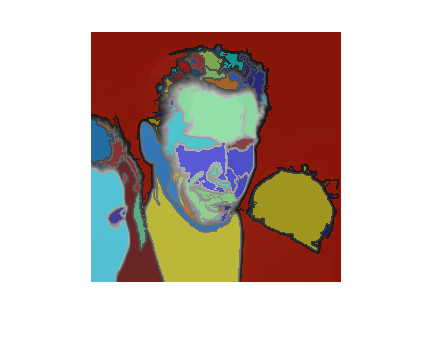


% label the regions delimited by the boundaries
[pieces_labeled, n_pieces] = bwlabel(1 - gmag);    

% display the distinct regions found
regions = labeloverlay(im_ocbr,pieces_labeled);
imshow(regions)

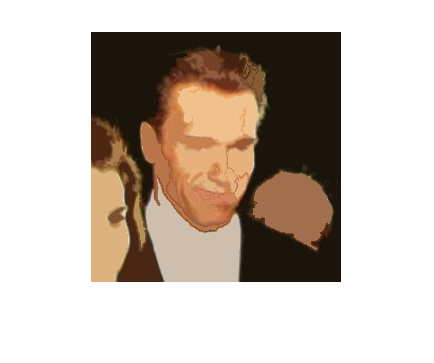


% fill edges with original colors
result = im .* gmag;
% color each region with its mean value
for i=1 : n_pieces
    % region mask
    mask = pieces_labeled == i;
    % compute the mean color value of the region
    n_pixel = sum(mask(:));
    mean_color = sum(reshape(im .* mask, [], 3) ,1)/n_pixel;
    % adjust the color
    [~, i] = max(mean_color);
    mean_color(i) = mean_color(i).^gamma;

    result = result + repmat(mask, 1, 1, 3) .* reshape(mean_color, 1,1,3);
end
imshow(result)